# Epidemiological Model for COVID19 Pandemic in Colombia

Universidad Nacional de Colombia, July 2020

Authors:

- Juan Diego Ocampo M.

- Carlos Eduardo Aguilar B.

- Sebastián Ruiz T.

- María Camila Muñoz.

## 1. Reset Simulation

clc
clearvars
close all
warning('off')

## 2. Problem Guidelines

totalPopulation = 48.9e6;                                       % Total Population (2018)
vaccineEffectiveness = 0.7;                                     % Number between 0.1 and 1
vaccineCost = 5;                                                % Vaccine cost in USD.
conversionRate = 3758.05;                                       % 1 USD to COP conversion ratio.
availableBudget = 10e9 / conversionRate                         % Available budget (in USD)
availableDoses = floor(availableBudget/vaccineCost)             % Available Doses (Vaccine)

## 3. Data Processing

Explain code here....

### 3.1 Importing Data

data = importCSV('Colombia_COVID19.csv')

data = 118×7 table
    NUEVOS_CASOS    TOTAL_CASOS    TOTAL_MUERTES    TOTAL_RECUPERADOS    FECHA_ACTUALIZACION    NUEVOS_MUERTOS    NUEVO_RECUPERADOS
    ____________    ___________    _____________    _________________    ___________________    ______________    _________________

          1               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          0               1              0                  0                    NaT                  0                   0        
          2               3              0                  0                    N

dailyInfections = data.NUEVOS_CASOS;                                    % Daily Infections
dailyDeaths = data.NUEVOS_MUERTOS;                                      % Daily Fatalities
dailyRecoveries = data.NUEVO_RECUPERADOS;                               % Daily Recoveries
totalInfections = data.TOTAL_CASOS;                                     % Total Infections
totalDeaths = data.TOTAL_MUERTES;                                       % Total Fatalities
totalRecoveries = data.TOTAL_RECUPERADOS;                               % Total Recoveries
susceptiblePopulation = totalInfections - totalRecoveries;              % Infected Remnants
timeElapsed = 1 : length(data.FECHA_ACTUALIZACION);                     % Elapsed Time since Patient Zero (in Days)

### 3.2 Data Visualisation

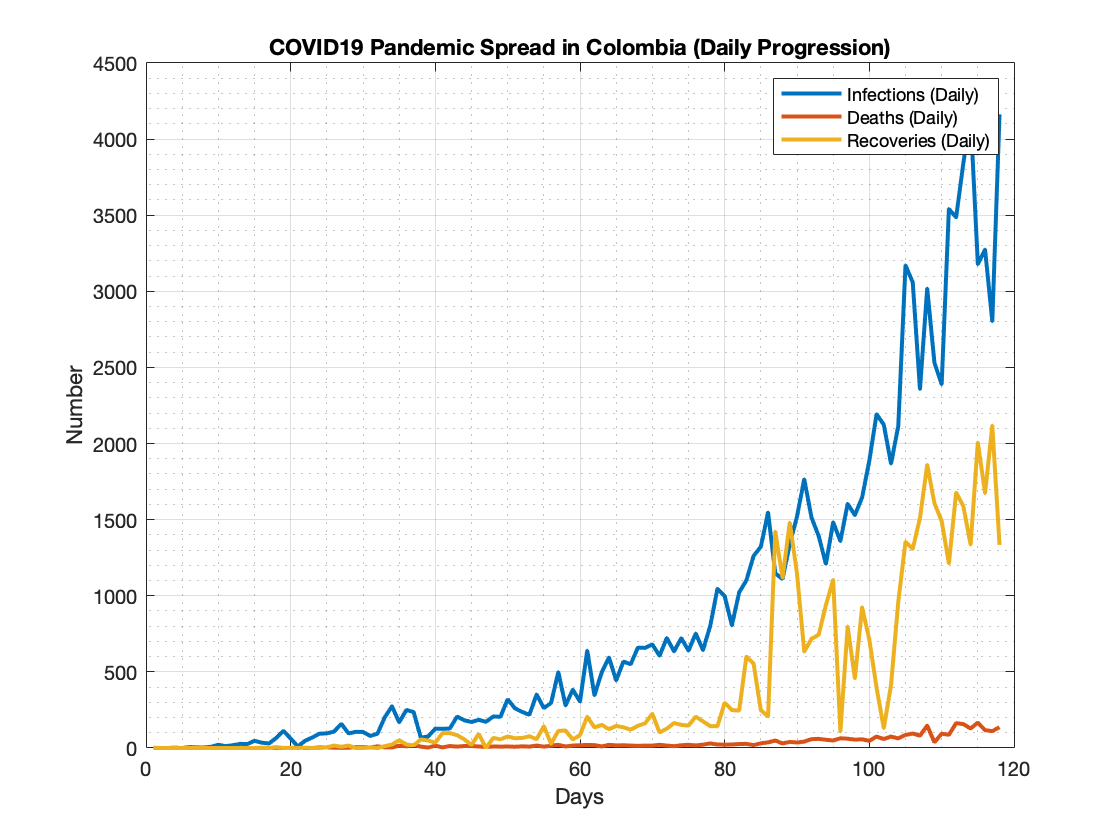

plot(timeElapsed,dailyInfections,timeElapsed,dailyDeaths,timeElapsed, dailyRecoveries, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Daily Progression)')
legend('Infections (Daily)','Deaths (Daily)','Recoveries (Daily)')
grid on, grid minor

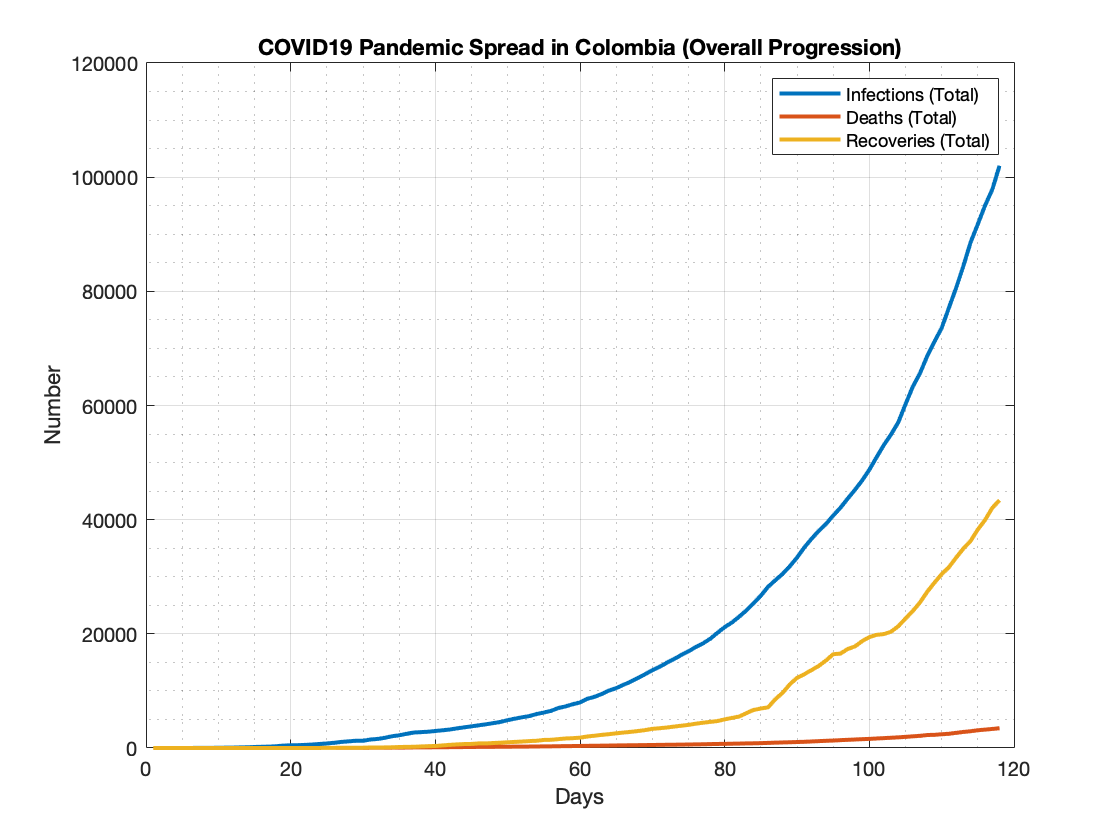

plot(timeElapsed,totalInfections,timeElapsed,totalDeaths,timeElapsed, totalRecoveries, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Days'), ylabel('Number'), title('COVID19 Pandemic Spread in Colombia (Overall Progression)')
legend('Infections (Total)','Deaths (Total)','Recoveries (Total)')
grid on, grid minor

#### 3.2.1 Fitting Curve to a Fifth Order Gaussian Model

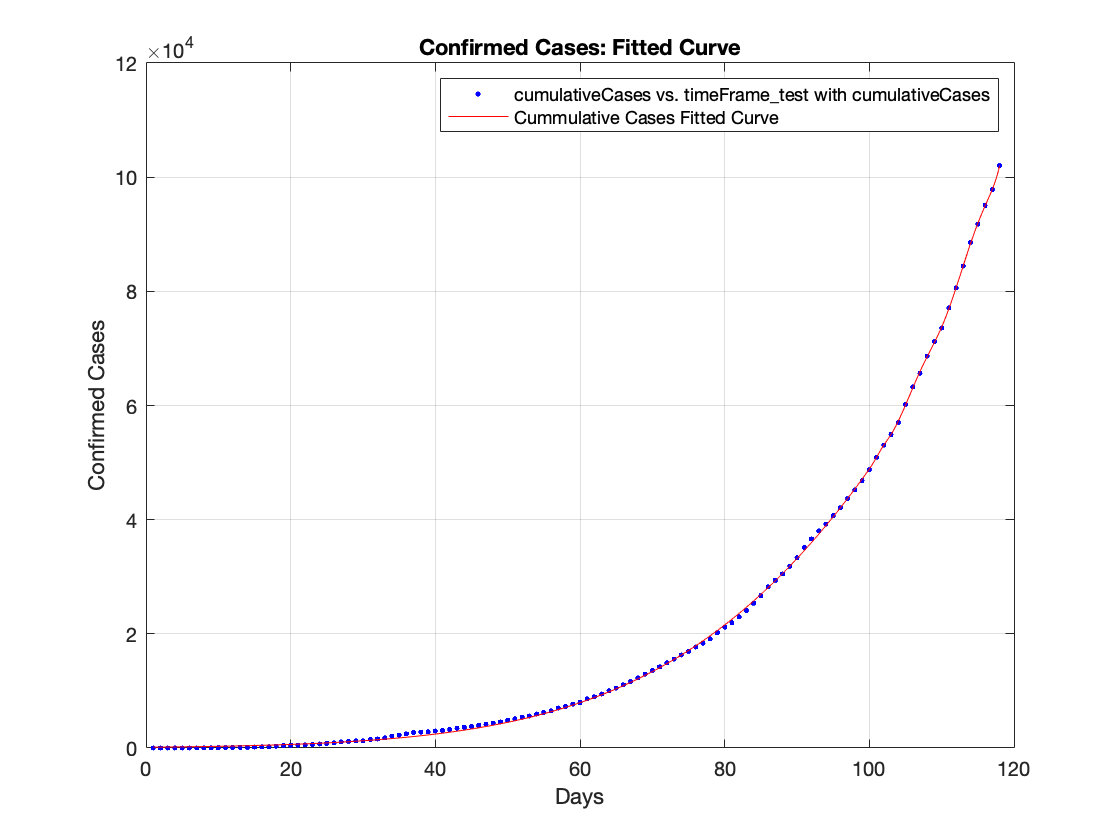

fittedCurve_cases = createFit(timeElapsed, data.TOTAL_CASOS);
xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases: Fitted Curve')

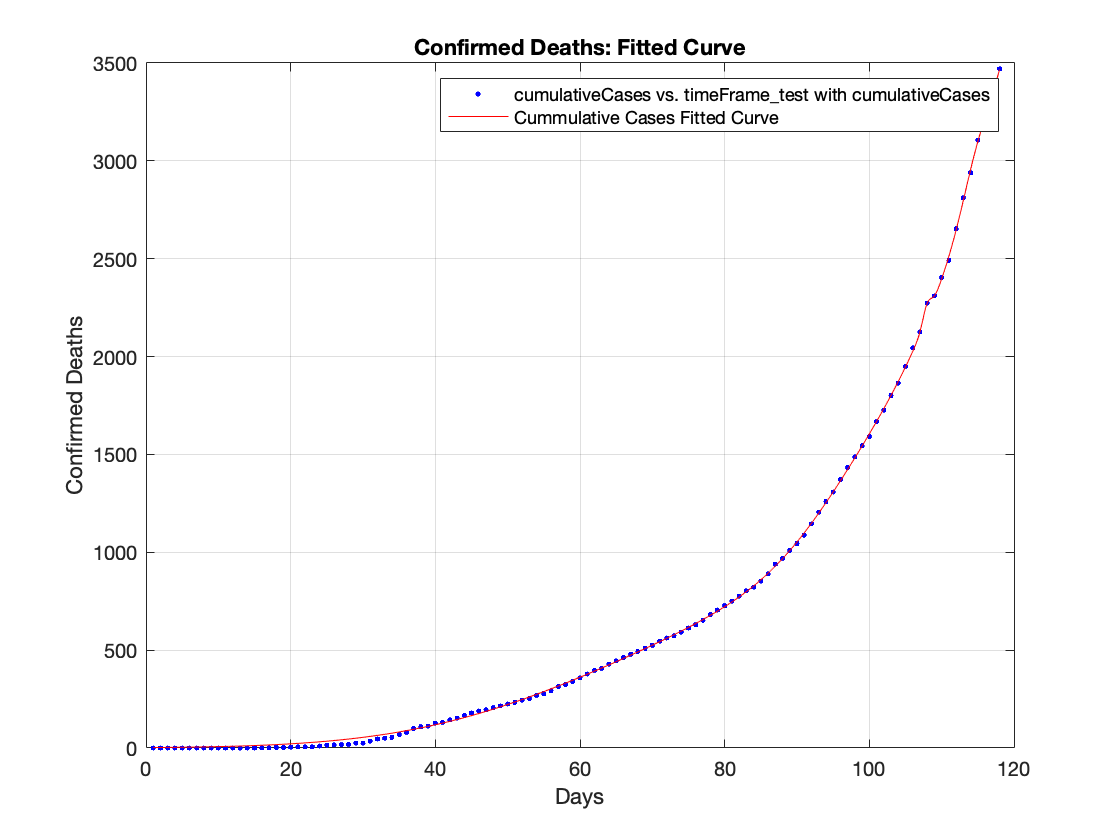

fittedCurve_deaths = createFit(timeElapsed, data.TOTAL_MUERTES);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths: Fitted Curve')

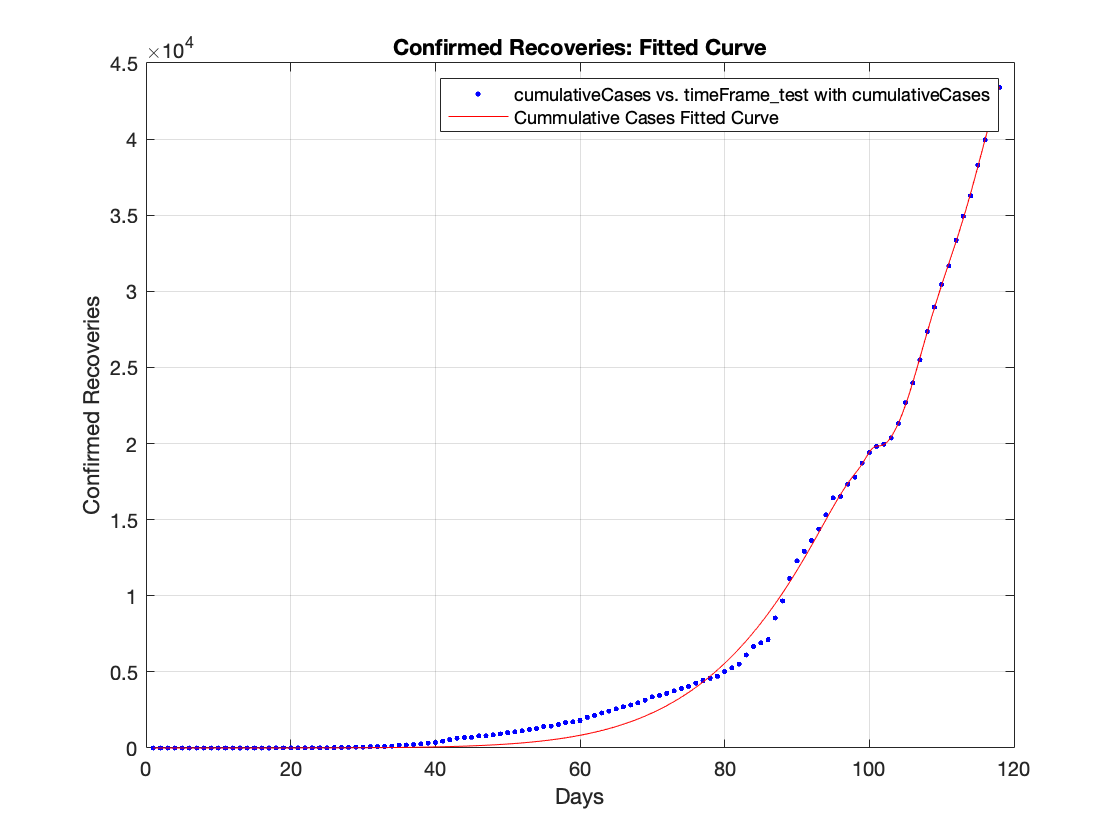

fittedCurve_recoveries = createFit(timeElapsed, data.TOTAL_RECUPERADOS);
xlabel('Days'), ylabel('Confirmed Recoveries'), title('Confirmed Recoveries: Fitted Curve')

## 4. Computing Disease Spread Model

Explain SEIRS model here...

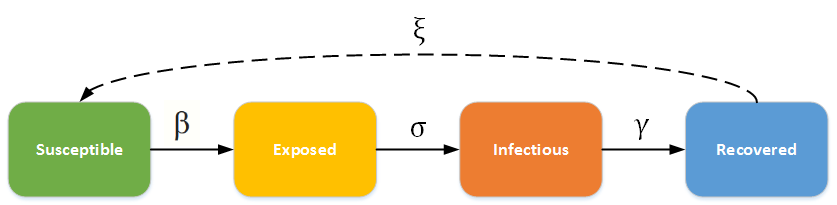

### 4.1 Computing Model Parameters

#### 4.1.1 Infectious Rate ($\beta$)

beta = n*[0 diff(susceptible_real)']./(-1.*(susceptible_real.*infected_real)); % Infectious Rate
b(b==inf) =[]; 
b(b==-inf)=[]; 
b(isnan(b)) = []; 
b=reshape(b,[1,length(b)^2]); 
b=median(b) 

#### **4.1.2 Incubation Rate (**$\sigma$)

D = 14;                                                     % Incubation Period (in Days)
sigma = 1 / D                                               % Incubation Rate

#### **4.1.3 Recovery Rate (**$\gamma$)

gamma=([0 diff(recovered_real)']./infected_real); 
gamma(gamma==inf) =[]; 
gamma(gamma==-inf)=[]; 
gamma(isnan(gamma)) = []; 
  
gamma=reshape(gamma,[1,length(gamma)^2]); 
gamma=median(gamma) 

#### 4.1.4 Inmunity Loss Rate ($\xi$)

inmunityLossRate = 0.7;                                         % Inmunity Loss Rate

**4.1.5 Birth Rate (**$\mu$**)**

Information retrieved from: *https://en.wikipedia.org/wiki/Demographics_of_Colombia*

birthRate = 18.9;                                               % Birth Rate (2020)                            

#### 4.1.6 Death Rate ($\nu$)

Information retrieved from: *https://en.wikipedia.org/wiki/Demographics_of_Colombia*

deathRate = 5.8;                                                % Death Rate (2020)    

### 4.2 Computing SEIRS Model Differential Equation

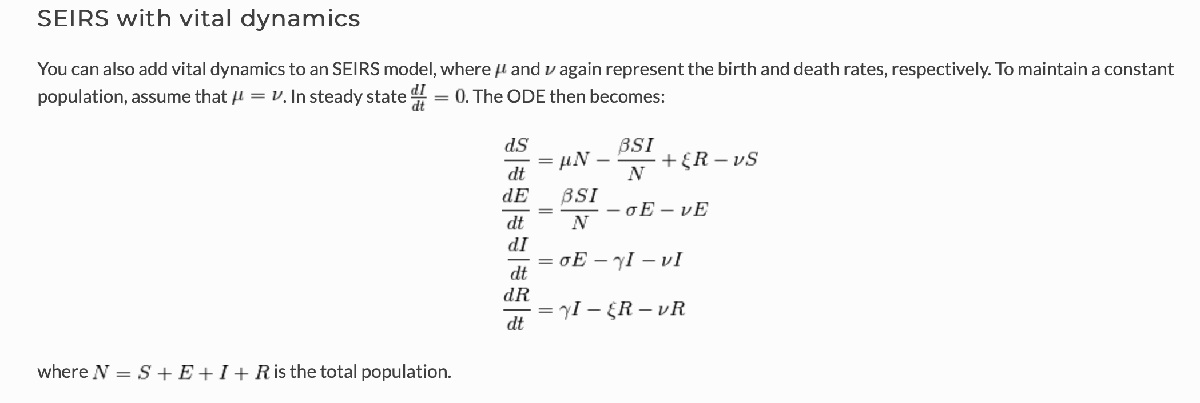

syms N(t) S(t) E(t) I(t) R(t) mu nu beta epsilon sigma gamma t

eqn1 = diff(S) == mu*N - beta*(S*I/N) + epsilon*R - nu*S;
eqn2 = diff(E) == beta*(S*I/N) - sigma*E - nu*E;
eqn3 = diff(I) == sigma*E - gamma*I - nu*I;
eqn4 = diff(R) == gamma*I - epsilon*R - nu*R;

seirsModelEqnSys = [eqn1; eqn2; eqn3; eqn4]

$$seirsModelEqnSys(t) = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}S\left(t\right)=\epsilon \,R\left(t\right)+\mu \,N\left(t\right)-\nu \,S\left(t\right)-\sigma_{1}\\ \frac{\partial }{\partial t}\text{E}\left(t\right)=\sigma_{1}-\sigma_{3}-\nu \,\text{E}\left(t\right)\\ \frac{\partial }{\partial t}\text{I}\left(t\right)=\sigma_{3}-\nu \,\text{I}\left(t\right)-\sigma_{2}\\ \frac{\partial }{\partial t}R\left(t\right)=\sigma_{2}-\epsilon \,R\left(t\right)-\nu \,R\left(t\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\beta \,\text{I}\left(t\right)\,S\left(t\right)}{N\left(t\right)}\\ \sigma_{2}=\gamma \,\text{I}\left(t\right)\\ \sigma_{3}=\sigma \,\text{E}\left(t\right) \end{array}$$


seirsModelEqnSys_SOLUTION = solve(seirsModelEqnSys,t)

 
seirsModelEqnSys_SOLUTION =
 
[ empty sym ]
 


...